clear, close all, clc


1.

die_vals = [1 2 3 4 5 6];
num_dies = 2;

num_side_die = length(die_vals);


Prob_snakeeye = (1/num_side_die)^2

Prob_snakeeye = 0.0278


num_sevens = 0;
for k = 1:length(die_vals)
    die1_val = die_vals(k);
    for j = 1:length(die_vals)
        die2_val = die_vals(j);
    if die1_val + die2_val == 4
        num_sevens = num_sevens + 1;
    end
    end
end

Prob_sevens = (num_sevens/(num_side_die^num_dies))

Prob_sevens = 0.0833


Ratio_probs = Prob_sevens/Prob_snakeeye

Ratio_probs = 3

The probability of rolling snake eyes is 2.78%, the probability of rolling sevens is 8.33% and the ratio of probabilities is 3.

2. Analytic Proof


$$P_{A+B}(x)=\int_{}^{}P_{A}(z)P_{b}(x-z)\,dz=P_{A}(x)*P_{B}(x)$$


Lets take the same example from above but lets use the number of fours we are able to get. We can get 4 by either adding 1 and 3, 2 and 2, and 3 and 1.


$$P_{1}(x) = \frac{1}{6}, P_{2}(x) = \frac{1}{6}, P_{3}(x) = \frac{1}{6}$$


Lets substitute in the numbers and since we are dealing with die which have only 6 distinct possibilities wee can use the summation operator rather then the integrator operator.


$$P_{1+3}(x)=\sum_{n=1}^{4}P_{1}(n)P_{3}(x-n)$$



$$P_{1+3}(x) = P_{3}(4-1)P_{1}(1)+P_{3}(4-2)P_{1}(2)+P_{3}(4-3)P_{1}(3)+P_{3}(4-4)P_{1}(4)$$



$$P_{1+3}(x) = \frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+0\frac{1}{6}=\frac{3}{36}$$


Now lets check with 2+2 just to make sure that wasn't a mistake


$$P_{2+2}(x) = P_{2}(4-1)P_{2}(1)+P_{2}(4-2)P_{1}(2)+P_{2}(4-3)P_{2}(3)+P_{2}(4-4)P_{1}(4)$$



$$P_{2+2}(x) = \frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+0\frac{1}{6}=\frac{3}{36}$$


Now lets do it with code

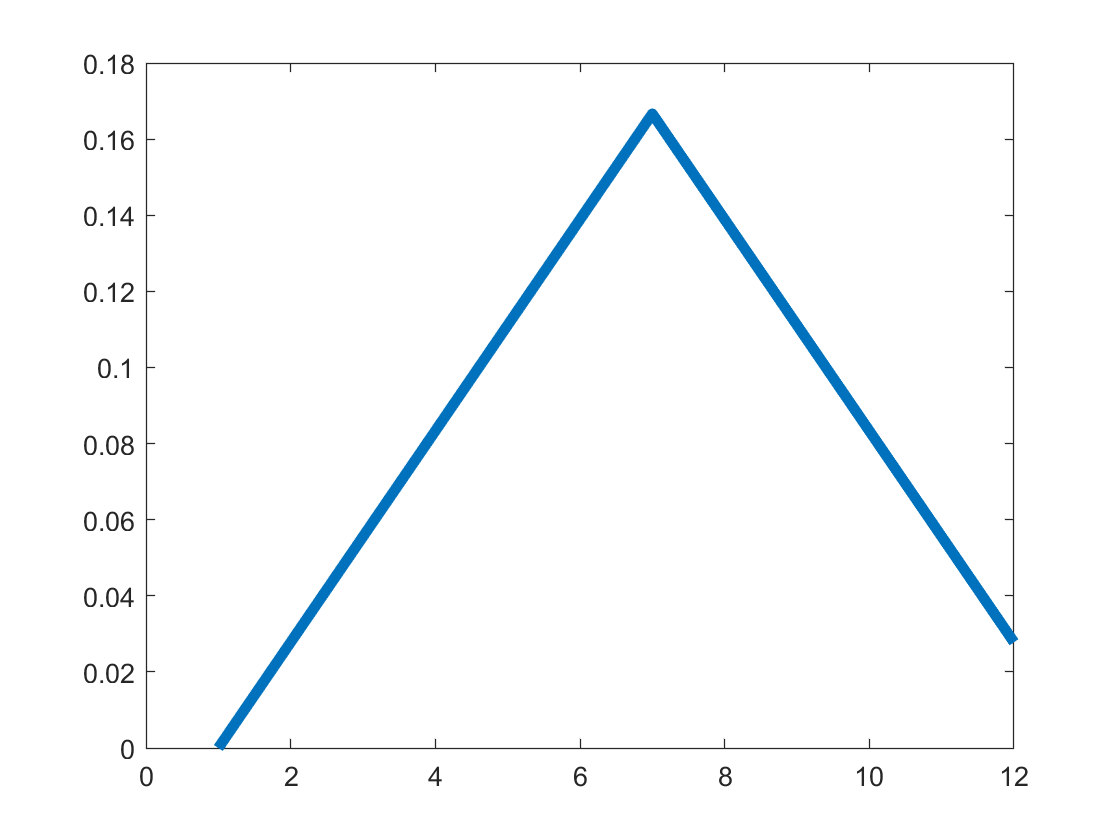

Prob_1 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_3 = [1/6 1/6 1/6 1/6 1/6 1/6];
uh = zeros(1,12);
uh(1) = 0;
uh(2:12)=conv(Prob_1,Prob_3);
x = 1:12;
plot(uh, 'Linewidth', 4)


prob_fours = uh(4)

prob_fours = 0.0833

We notice that 3/36 = 8.33% which agrees with our analytic approach.

3. Now lets calculate the mean and variance of the dist. I used the weighted mean formula below to calculate the mean. 


$$\bar{x}=\frac{\sum^{N}_{i=1}x_{i}w_{i}}{\sum^{N}_{i=1}w_{i}}$$


Using matlabs built in variance command I get a variance of 5.8333. Matlabs command uses  $V=\frac{1}{N-1}\sum^{N}_{i=1}|{A_{i}-\mu}|^{2}$ 

where $\mu$ is the mean of $A$.


$$\mu = \frac{1}{N}\sum^{N}_{i=1}A_{i}$$


mean_conv = sum(uh.*x)/sum(uh, 'all')

mean_conv = 7.0000



V = var(x,uh)

V = 5.8333

4. Lets graph the average of 10 dice rolls

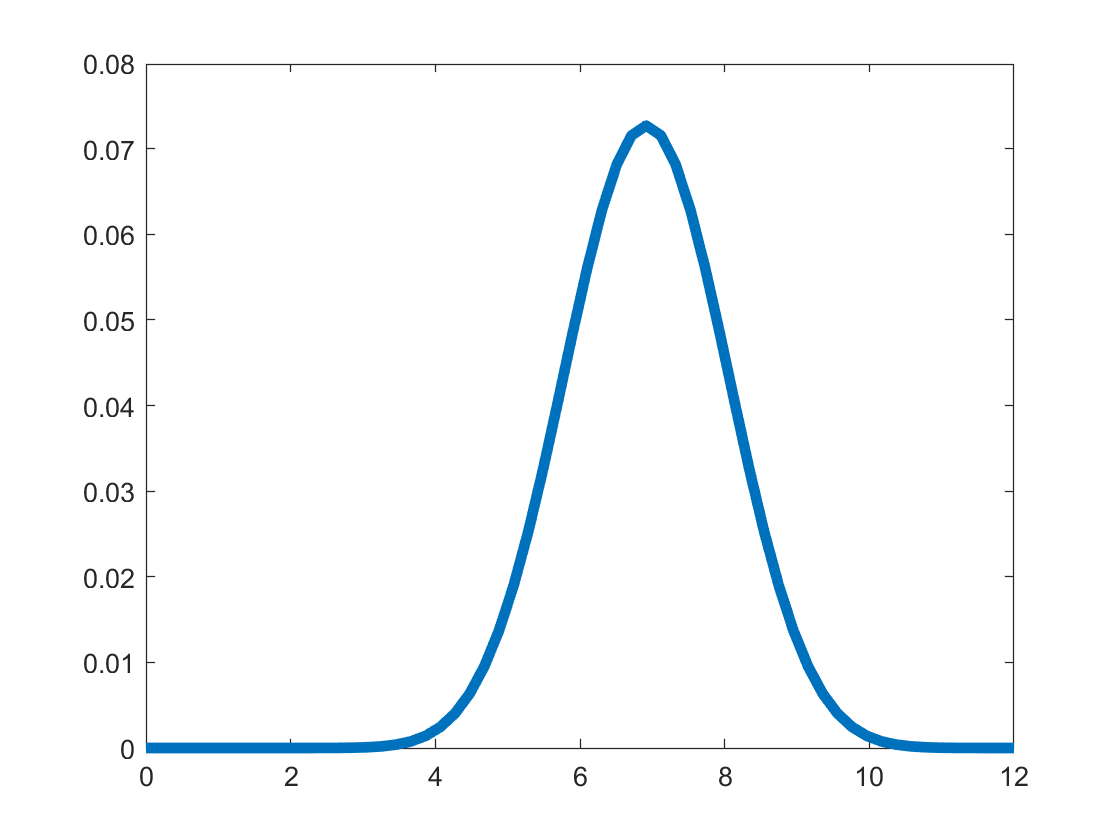

Prob_1 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_2 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_3 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_4 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_5 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_6 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_7 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_8 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_9 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_10 = [1/6 1/6 1/6 1/6 1/6 1/6];
uh = zeros(1,60);
uh(1:10) = zeros(1,10);
uh(10:60)=conv(conv(conv(conv(conv(conv(conv(conv(conv(Prob_1, Prob_2), Prob_3), Prob_4), Prob_5), Prob_6), Prob_7), Prob_8), Prob_9), Prob_10);
x = linspace(0,12,60);
plot(x,uh, 'Linewidth', 4)


mean_conv = sum(uh.*x)/sum(uh, 'all')

mean_conv = 6.9153

Essentially what we are doing is superimposing ten of the original triangular looking plots on top each other. The more plots you add the more gaussian the distribution will appear to be due the central limit theorem. 

Lets analytically prove that the sum of two independent Gaussian distributions is also a Gaussian Distribution

The form of the $PDF$of a Gaussian Distribution is:


$$PDF_x(X)=\frac{1}{\sqrt{2\pi}\sigma_{x}}e^\frac{{-(X-\mu_{x})^{2}}}{2\sigma_{x}^{2}}$$



$$PDF_y(Y)=\frac{1}{\sqrt{2\pi}\sigma_{y}}e^\frac{{-(Y-\mu_{y})^{2}}}{2\sigma_{y}^{2}}$$


Where $\sigma$= the standard of deviation and $\mu$= the mean of the distribution. Since we want to prove essentially that $Z = X + Y$we can use the definition of a convolution to help


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}PDF_{x}(X)PDF_{y}(Z-X)\,dX$$


where $Y = Z-X$

The general idea here is to substitute the values for the two $PDF$ functions into the equation and then do some algebra and calculus until it resembles the general form of a single $PDF$function as listed above.


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}\frac{1}{\sqrt{2\pi}\sigma_{x}}e^\frac{{-(X-\mu_{x})^{2}}}{2\sigma_{x}^{2}}\frac{1}{\sqrt{2\pi}\sigma_{y}}e^\frac{{-(Z-X-\mu_{y})^{2}}}{2\sigma_{y}^{2}}\,dX$$


Lets combine the two exponents and two fractions


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}\frac{1}{2\pi\sigma_{x}\sigma_{y}}e^\frac{{-\sigma_{y}^{2}(X-\mu_{x})^{2}+\sigma_{x}^{2}(Z-X-\mu_{y})^{2}}}{2\sigma_{x}^{2}\sigma_{y}^{2}}\,dX$$


Now lets factor out some of those terms stuck up in the exponent


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}\frac{1}{2\pi\sigma_{x}\sigma_{y}}e^\frac{{-X^{2}(\sigma_{x}+\sigma_{y})-2X(\sigma_{x}^{2}(z-\mu_{y})+\sigma_{y}^{2}\mu_{x})+\sigma_{x}^{2}(z^{2}+\mu_{y}^{2}-2Z\mu_{y})+\sigma_{x}^{2}\mu_{x}}}{2\sigma_{x}^{2}\sigma_{y}^{2}}\,dX$$


Lets start trying to shift it into the form of a $PDF$ by taking $\sigma_{z}=\sqrt{\sigma_{x}^{2}+\sigma_{y}^{2}}$


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}\frac{1}{\sqrt{2\pi}\sigma_{z}}\frac{1}{\sqrt{2\pi}\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}}}\exp\left[\frac{X^{2}-2X\frac{\sigma_{x}^{2}(Z-\mu_{z})+\sigma_{y}^{2}\mu_{x}}{\sigma_{z}^{2}}+\frac{\sigma_{x}^{2}(Z^{2}+\mu_{y}^{2}-2Z\mu_{y})+\sigma_{y}^{2}\mu_{x}^{2}}{\sigma_{z}^{2}}}{2(\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}})^{2}}\right]\,dX$$


Now lets start splitting up the exponent


$$PDF_{z}(Z)=\int_{-\infty}^{\infty}\frac{1}{\sqrt{2\pi}\sigma_{z}}\exp\left[-\frac{\sigma_{z}^{2}(\sigma_{x}^{2}(z-\mu_{y})^{2}+\sigma_{y}^{2}\mu_{x}^{2})-(\sigma_{x}^{2}(z-\mu_{y})+\sigma_{y}^{2}\mu_{x})^{2}}{2\sigma{z}^{2}(\sigma{x}\sigma{y})^{2}}\right]\frac{1}{\sqrt{2\pi}\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}}}\exp\left[\frac{\left(X-\frac{\sigma_{x}^{2}(Z-\mu_{z})+\sigma_{y}^{2}\mu_{x}}{\sigma_{z}^{2}}\right)^{2}}{2(\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}})^{2}}\right]\,dX$$


Lets keep condensing the form.


$$PDF_{z}(Z)=\frac{1}{\sqrt{2\pi}\sigma_{z}}\exp\left[-\frac{(z-(\mu_{x}+\mu_{y}))^{2}}{2\sigma{z}^{2}}\right]\int_{-\infty}^{\infty}\frac{1}{\sqrt{2\pi}\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}}}\exp\left[\frac{\left(X-\frac{\sigma_{x}^{2}(Z-\mu_{z})+\sigma_{y}^{2}\mu_{x}}{\sigma_{z}^{2}}\right)^{2}}{2(\frac{\sigma_{x}\sigma_{y}}{\sigma_{z}})^{2}}\right]\,dX$$


At this point we can realize that the integral is just a normal density distribution and thus becomes 1. Which finally results in an expression for $PDF_{z}$ which resembles the general form for a $PDF$ for a gaussian distribution.


$$PDF_{z}(Z)=\frac{1}{\sqrt{2\pi}\sigma_{z}}\exp\left[-\frac{(z-(\mu_{x}+\mu_{y}))^{2}}{2\sigma{z}^{2}}\right]$$


To find the average of $PDF_{x}$ and $PDF_{y}$ simply take the average of there respective $\sigma$'s and $\mu$'s. 


$$\sigma_{z} = \sqrt{\frac{\sigma_{x}^{2}+\sigma_{y}^{2}}{4}}, \mu_{z}=\frac{\mu_{x}+\mu_{y}}{2}$$


Then substitude these values into the general form for a $PDF$


$$PDF_z(Z)=\frac{1}{\sqrt{2\pi}\sigma_{z}}e^\frac{{-(Z-\mu_{z})^{2}}}{2\sigma_{z}^{2}}$$


The standard deviations for the sum and average is $\sigma_{sum} = \sqrt{\sigma_{x}^{2}+\sigma_{y}^{2}}, \sigma_{average}=\sqrt{\frac{\sigma_{x}^{2}+\sigma_{y}^{2}}{4}}$

Overtime the signal would become more pronounced as it would be increasingly unlikely that the background could have caused it. 